# RESULT: Arm Shape Comparison

*MATLAB Version: '23.2.0.2409890 (R2023b) Update 3'*

*Last revised: 8/17/2024*

*Authors: Bill Fan*

This document should contain all that is necessary for the RESULTS subsection on applying the attainability methods for comparing different overall arm shapes for reaching a specific tip pose and load configuration.

First, we will define a target task, which comprises of a target tip pose and tip load. For this example we will approximate a drawer-opening task.

%% Step 1: Define target trajectory keybpoints
% Base pose: hanging down
pose_base = [0; 0; -pi/2];

% Keypoint poses: [x y theta]
pose_1 = [0.1; -0.05; 0];

poses = [pose_1];

% Create load vector
qx = 5; % Load of opening the drawer: 1N
Q = [qx; 0; 0]; % If we move to the left to open the drawer, then the drawer force will pull to the right

We will compare a variety of "heuristic" based shape-planning methods. Each heuristic is formulated as a cost function - for example, the observation "the best shape minimizes curvatures" associates each arm shape's cost with the sum of the curvatures.

% Step 2: 
N_nodes = 10;

cell_cost_funcs = {
    @(mat_geom) base_curve_cost_sum_of_dists_from_target_squared(mat_geom, [100, 1]), ...
    @(mat_geom) base_curve_cost_sum_of_dists_from_target_squared(mat_geom, [40.3, 1]), ...
    @(mat_geom) base_curve_cost_sum_of_dists_from_target_squared(mat_geom, [40, 1]), ...
    @(mat_geom) base_curve_cost_sum_of_dists_from_target_squared(mat_geom, [30, 1]), ...
    @(mat_geom) base_curve_cost_sum_of_dists_from_target_squared(mat_geom, [20, 1]), ...
};
names = ["[100, 1]", "[40.3, 1]", "[40, 1]", "[30, 1]", "[20, 1]"];

cell_g_circ = cell(size(cell_cost_funcs));

for i_shape = 1 : numel(cell_g_circ)
    cost_func_i = cell_cost_funcs{i_shape};
    cell_g_circ(i_shape) = find_shape_single_seg(pose_base, poses, Q, N_nodes, cost_func_i);
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat

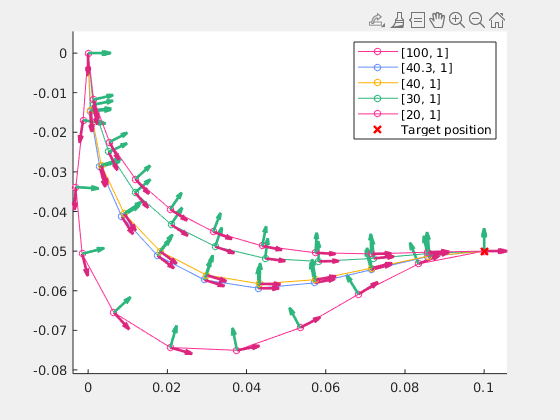


ax = axes(figure("Visible", true));
hold on;
g_0 = Pose2.hat(pose_base);

color_green = [45 182 125] / 255;
color_yellow = [255 176 0] / 255;
color_blue = [100 143 255] / 255;
color_red = [255 48 150] / 255;

colors = [color_red; color_blue; color_yellow; color_green];

colors = [colors; colors];

for i_shape = 1 : numel(cell_g_circ)
    segment_twists_i = cell_g_circ{i_shape};
    poses_i = calc_poses(g_0, segment_twists_i);
    linestyle = struct("color", colors(i_shape, :), "Marker", "o", "Markersize", 5, "Displayname", names(i_shape));
    plot_poses(poses_i, ax, linestyle, true);
end
plot(poses(1, :), poses(2, :), 'rx', "MarkerSize", 7, "Linewidth", 2, "Displayname", "Target position")
legend()

function cost = base_curve_cost_sum_of_dists_from_target_squared(mat_geom, w)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    all_twists = [cell_g_circ_right{:}];
    all_ls = all_twists(1, :);
    all_curvatures = all_twists(3, :);

    target_l = 0.17;
    dist_from_target_l = all_ls - target_l;
    indiv_costs = [norm(dist_from_target_l); norm(all_curvatures)];
    cost = dot(w, indiv_costs);
end

function mat_g_circ_right = v_geom_to_g_circ(v_geom)
    % Convert a "geometry vector" to a matrix of twists
    % By "geometry vector" I mean [l_1; k_1; l_2; k_2; ...; l_n; k_n]
    n_g_circ = length(v_geom)/2;
    mat_l_k = reshape(v_geom, [2, n_g_circ]);
    lengths = mat_l_k(1, :);        % lengths
    shears = zeros(1, n_g_circ);    % shears
    curvatures = mat_l_k(2, :);     % curvatures

    mat_g_circ_right = [lengths; shears; curvatures];
end

function cell_g_circ_out = mat_geom_to_g_circ(mat_geom)
    % Convert a "geometry matrix" to a cell array of matrices of twists
    
    N_poses = size(mat_geom, 2);
    N_segs = size(mat_geom, 1) / 2;
    cell_g_circ_out = cell(1, N_poses);
    for i = 1 : N_poses
        v_geom_i = mat_geom(:, i);
        cell_g_circ_out{i} = v_geom_to_g_circ(v_geom_i);
    end
end